# Bi-linear Transformation for the Routh-Hurwitz Criterion & MATLAB

## The Bilinear Transformation: a Recap


$$z = \frac{w+1}{w-1}, \; z, \, w \in \mathbb C
\quad \quad \quad \quad\quad
\begin{array}{l}
\vert z \vert < 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) < 0 \\
\vert z \vert = 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) = 0 \\
\vert z \vert > 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) > 0
\end{array}$$


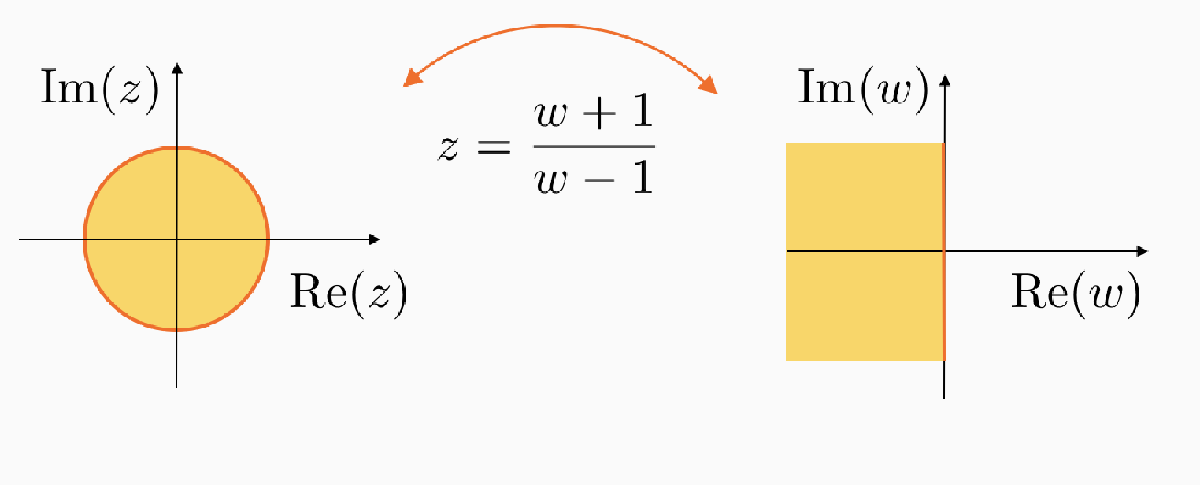

Substitute

 
$$z = \frac{w+1}{w-1}, \; z, \, w \in \mathbb C$$


into $p_A (z)  =
\varphi_0 z^n + \varphi_1 z^{n-1} + \cdots
+ \varphi_{n-1} z + \varphi_n$, thus obtaining


$$\begin{array}{l}
q_A (w)  = \, \left(w-1 \right)^n \,   \left[
\varphi_0 \frac{\left(w+1 \right)^n}{\left(w-1 \right)^n} + 
 \varphi_1 \frac{\left(w+1 \right)^{n-1}}{\left(w-1 \right)^{n-1}} + \cdots +
 \varphi_{n-1} \frac{\left(w+1 \right)}{\left(w-1 \right)} 
 +  \varphi_{n}
 \right ]
\end{array}$$


and hence one gets


$$q_A(w) = q_0 \, w^n + q_1\,w^{n-1}+\cdots+q_{n-1}\,w + q_n$$


with suitable coefficients $q_0, \, q_1, \ldots, q_n$.

## Applying the Bilinear Transformation In MATLAB

Given


$$p_A(z) \;=\; z^3+2\,z^2+z+1$$


one gets


$$q_A(w) \;=\;(w-1)^3 \, \left[ \displaystyle \frac{(w+1)^3}{(w-1)^3}+2\,
  \frac{(w+1)^2}{(w-1)^2}+\frac{w+1}{w-1}+1 \right]$$


and after some algebra


$$q_A(w) =5\,w^3+w^2+3\,w-1$$


Let us replicate the application of the bilinear transform using the *Symbolic Math Toolbox* in MATLAB.

clear
close all
clc

syms z w % let's declare a few symbolic variables

p_Az = z^3+2*z^2+z+1 % assign the characteristic polynomial 

$$p\_Az = z^{3}+2\,z^{2}+z+1$$

                     % to analyse, using the bilinear transform
                     
bTexpr = (w+1)/(w-1) % the bilinear transform                     

$$bTexpr = \frac{w+1}{w-1}$$

Now, using the `subs` command, let us compute the transformed polynomial

q_Aw = ((w-1)^3) * subs(p_Az,z,bTexpr)

$$q\_Aw = {\left(w-1\right)}^{3}\,\left(\frac{w+1}{w-1}+\frac{2\,{\left(w+1\right)}^{2}}{{\left(w-1\right)}^{2}}+\frac{{\left(w+1\right)}^{3}}{{\left(w-1\right)}^{3}}+1\right)$$

Finally, let us simplify the resulting expression

q_Aw = simplify(q_Aw)

$$q\_Aw = 5\,w^{3}+w^{2}+3\,w-1$$

What if the characteristic polynomial to be transformed $p_{A}(z)$ contains some parametric coefficients?

For example, consider the polynomial


$$p_A(z) = z^2 +a z +b \quad a , b \in \mathbb{R}$$


clear
clc
syms z w % the symbolic variables used to describe the polynomial and the bilinear transform
syms a b % the parametric coefficients

Now define the polynomial

p_Az = z^2+a*z +b

$$p\_Az = z^{2}+a\,z+b$$

and the bilinear transform

bTexpr = (w+1)/(w-1) % the bilinear transform 

$$bTexpr = \frac{w+1}{w-1}$$

Apply the bilinear transform

q_w = ((w-1)^2)*subs(p_Az,z,bTexpr)

$$q\_w = {\left(w-1\right)}^{2}\,\left(b+\frac{{\left(w+1\right)}^{2}}{{\left(w-1\right)}^{2}}+\frac{a\,\left(w+1\right)}{w-1}\right)$$

and simplify the result:

expand(q_w)

$$ans = \begin{array}{l} b-2\,b\,w+\frac{1}{\sigma_{1}}+b\,w^{2}-\frac{2\,w^{2}}{\sigma_{1}}+\frac{w^{4}}{\sigma_{1}}+\frac{a}{w-1}-\frac{a\,w}{w-1}-\frac{a\,w^{2}}{w-1}+\frac{a\,w^{3}}{w-1}\\ \mathrm{where}\\ \sigma_{1}=w^{2}-2\,w+1 \end{array}$$


simplify(expand(q_w))

$$ans = b-a+2\,w-2\,b\,w+a\,w^{2}+b\,w^{2}+w^{2}+1$$


q_w = collect(simplify(expand(q_w)),w)

$$q\_w = \left(a+b+1\right)\,w^{2}+\left(2-2\,b\right)\,w+b-a+1$$